# Rangefinder

**Overview**

The `Rangefinder` chart creates a visualization of bivariate scattered data together with horizontal and vertical lines representing marginal data statistics. Specifically, the chart comprises

- a 2D discrete plot containing the scattered $(x, y)$ data,

- a crosshair indicating the intersection of the marginal medians,

- vertical lines indicating the lower and upper adjacent values for the $x$ data,

- horizontal lines indicating the lower and upper adjacent values for the $y$ data.

The lengths of the lines are given by the marginal interquartile ranges. The *adjacent values* are the nearest data points inside the range determined by the lower and upper values. The *lower and upper values* are 1.5 interquartile ranges outside of the lower and upper quartiles, respectively. 

The chart data comprises numeric vectors `XData` and `YData`.

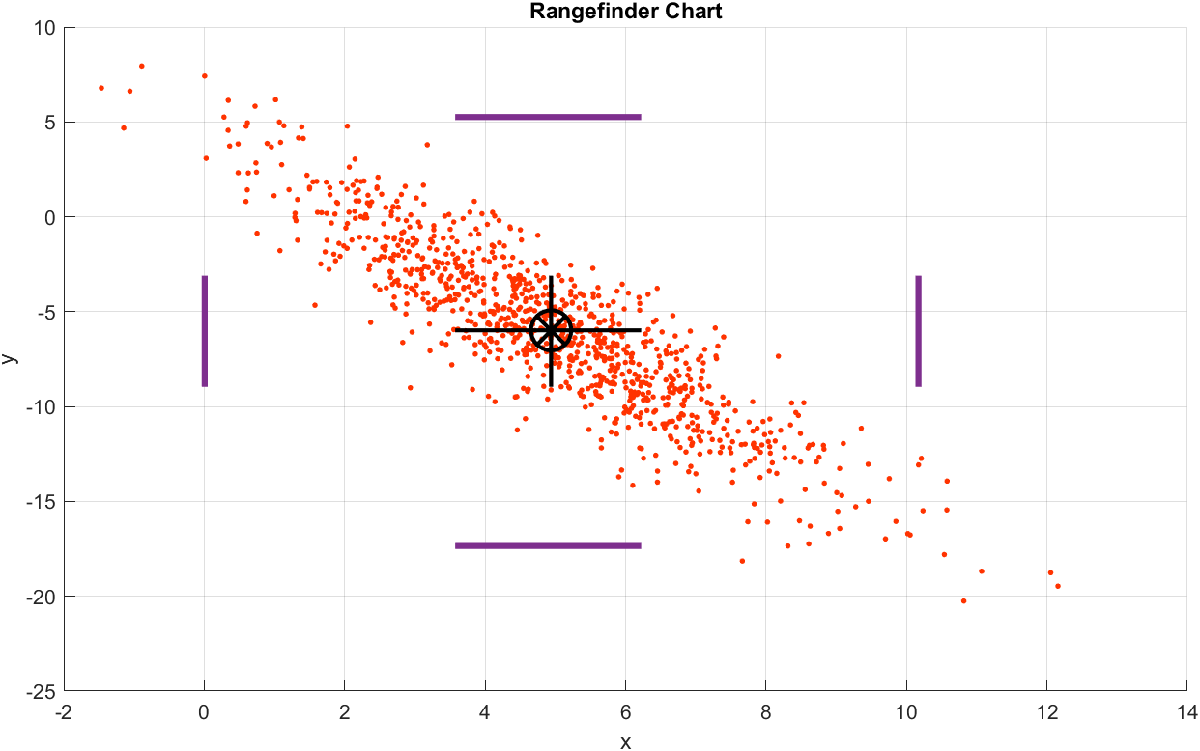

**Resources**

[Open](matlab: edit(fullfile(catalogRoot, "+example", "Rangefinder.mlx"))) this Live Script to run and interact with the examples shown below.

[View](matlab: edit(fullfile(catalogRoot, "+chart", "Rangefinder.m"))) the source code for the `Rangefinder` chart.

Martinez, W.L., Martinez, A.R. and Solka, J.L. 2011. *Exploratory Data Analysis with MATLAB (Second Edition), *Chapter 9, Section 9.5 (pp. 356-359). Boca Raton, Florida: Chapman and Hall/CRC Press, Taylor & Francis Group.

## Create sample chart data.

We start by defining sample $x$ and $y$ data vectors for the chart.

nPoints = 1000;
rng( "default" )
x = 2 * randn( nPoints, 1 );
y = 2 * x + 1 + 2 * randn( nPoints, 1 );

## Create a figure for the chart.

f = exampleFigure( "Name", "Rangefinder Example", "Color", "w" );

## Create the chart, specifying the parent and input data.

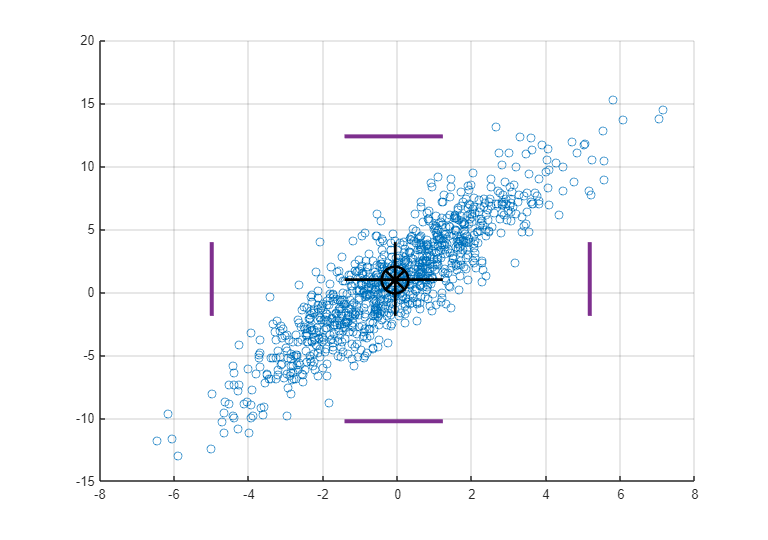

RF = chart.Rangefinder( "Parent", f, ...
    "XData", x, ...
    "YData", y );

## Annotate the chart.

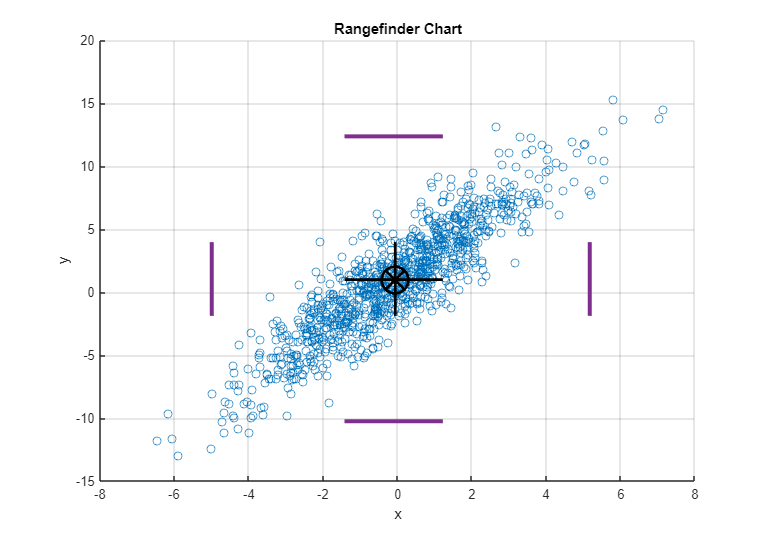

xlabel( RF, "x" )
ylabel( RF, "y" )
title( RF, "Rangefinder Chart" )

## Truncate the $x$ data of the chart.

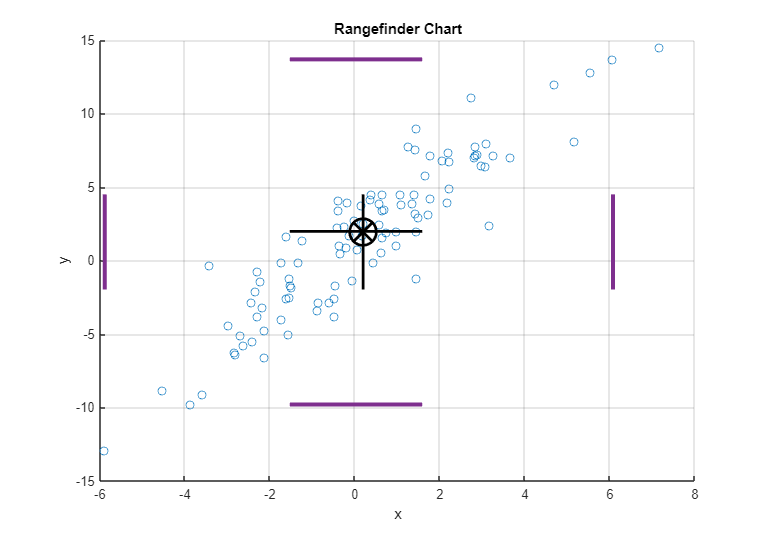

RF.XData = RF.XData(1:round(nPoints/10));

## Reinstate the original chart data.

RF.XData = x;
RF.YData = y;

## Modify the $y$ data of the chart.

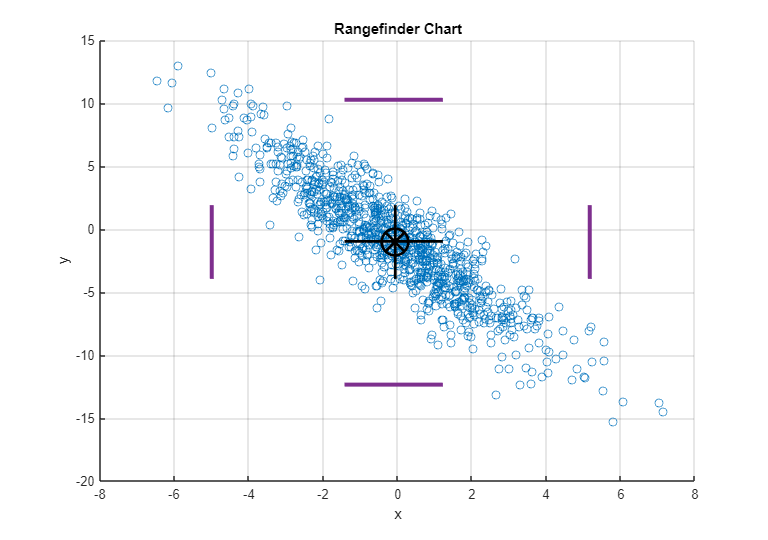

RF.YData = (-1) * RF.YData;

## Translate the chart data.

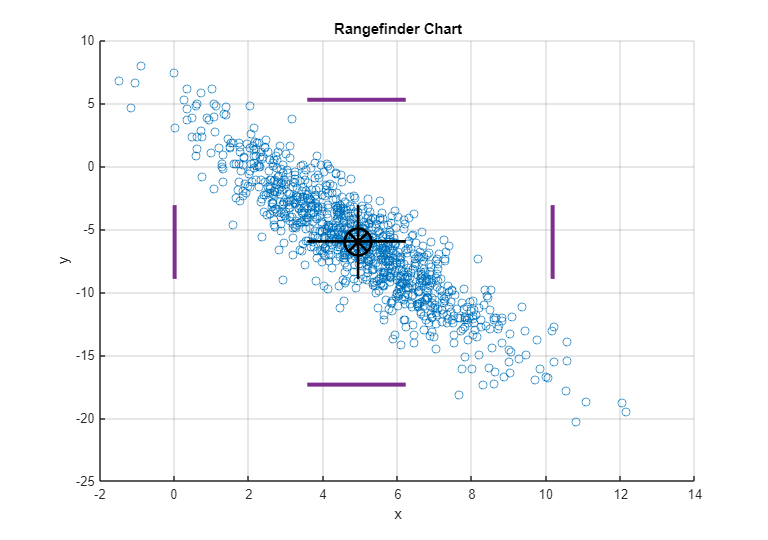

RF.XData = 5 + RF.XData;
RF.YData = -5 + RF.YData;

## Customize the chart appearance.

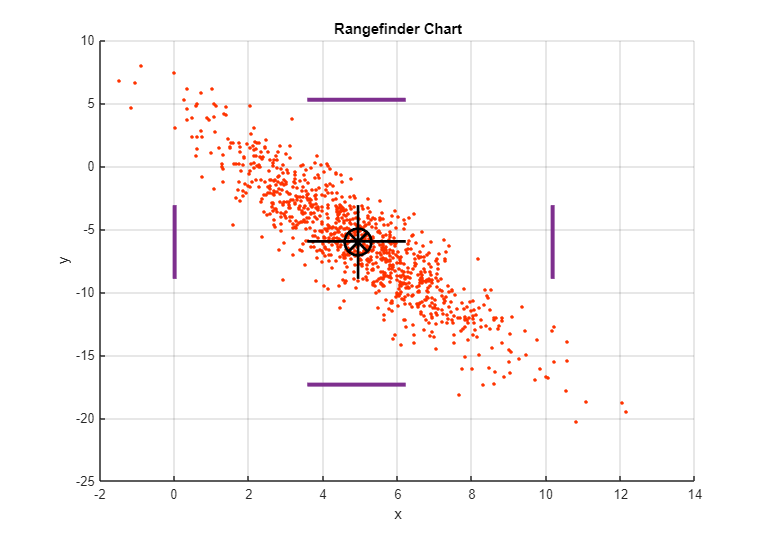

RF.Marker = ".";
RF.SizeData = 64;
RF.CData = [1, 0.2, 0];

*Copyright 2018-2021 The MathWorks, Inc.*